**AFSAH  HYDER**

**LAB 01**

**Relevance of this lab to DSP**:

- **Spectral Analysis**: The DFT is fundamental in analyzing signals in the frequency domain, crucial for filtering, compression, and feature extraction.

- **Signal Reconstruction**: The inverse DFT demonstrates that no information is lost in the transformation process, supporting applications in audio/image processing and communications.

- **Efficiency**: Understanding how to derive and compute DFTs manually is essential for optimizing algorithms like FFT in practical DSP applications.

**Activity 1.1**

- **fdft**: Calculates the DFT, transforming the time-domain signal into the frequency domain. visualizes the magnitude of the DFT components using a stem plot.

- **idft**: Calculates the IDFT, transforming the frequency-domain signal back to the time domain + stem plot

N=10;
x= ones(1,N);
disp("Activity 1.1")

Activity 1.1


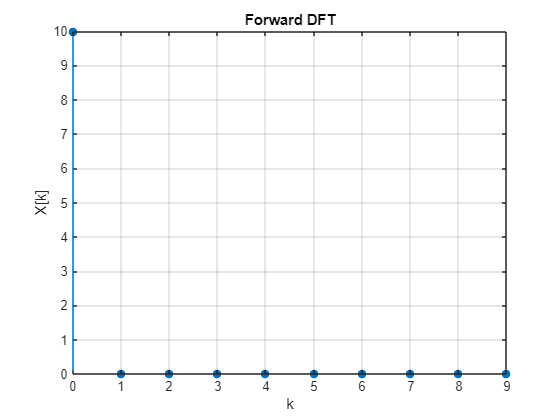

N_arr = 0:9;
% forward dft
X = fdft(x,N);

The output from the DFT shows how the input signal is represented in the frequency domain, which matches what’s outlined in the lab manual. 

It’s a bit surprising that the first spike is at 10, with all the others being 0. This can be explained by the fact that a constant input signal has no variations or oscillations, meaning it only contains a DC component (the constant term). This indicates that the entire energy of the signal is concentrated at k=0.

The other frequency components cancel out, so the spike at 10 represents the DC component, while the zeros indicate there are no other frequencies present in the signal.

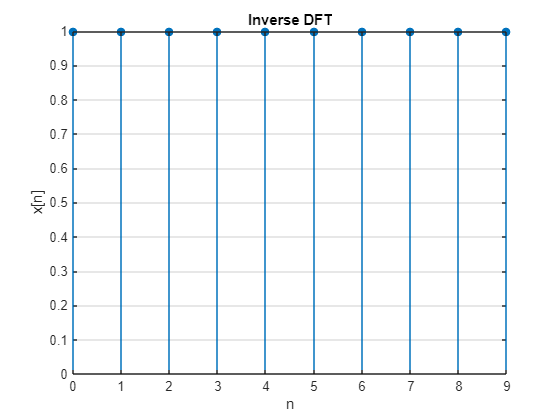

% INVERSE DFT
x_idft = idft(X,N);

Applying the inverse DFT reconstructs the original signal, confirming the correctness of the implementation.

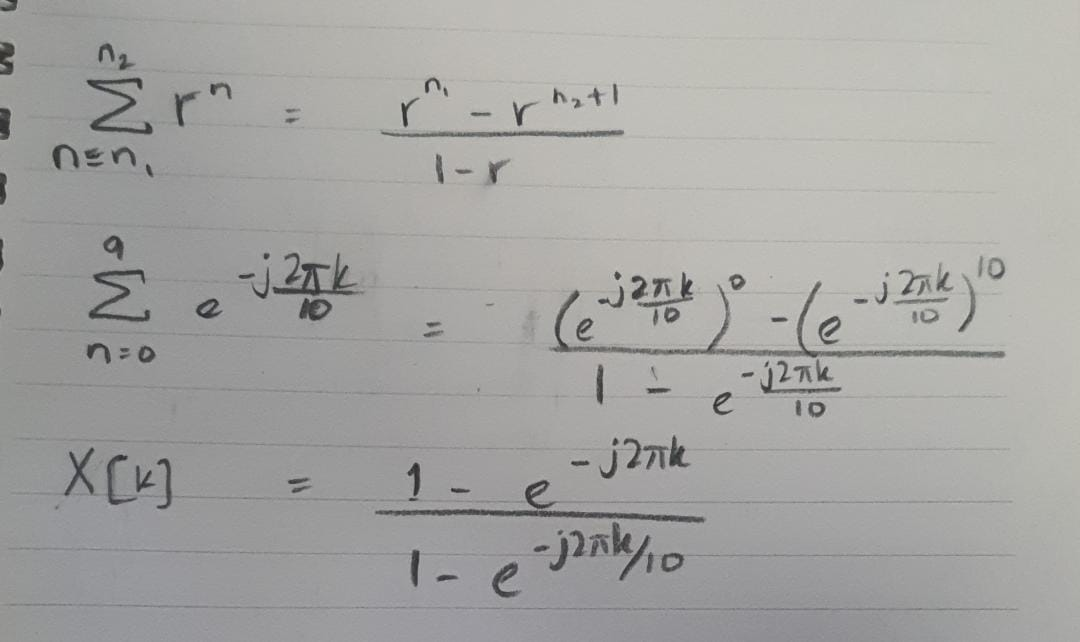

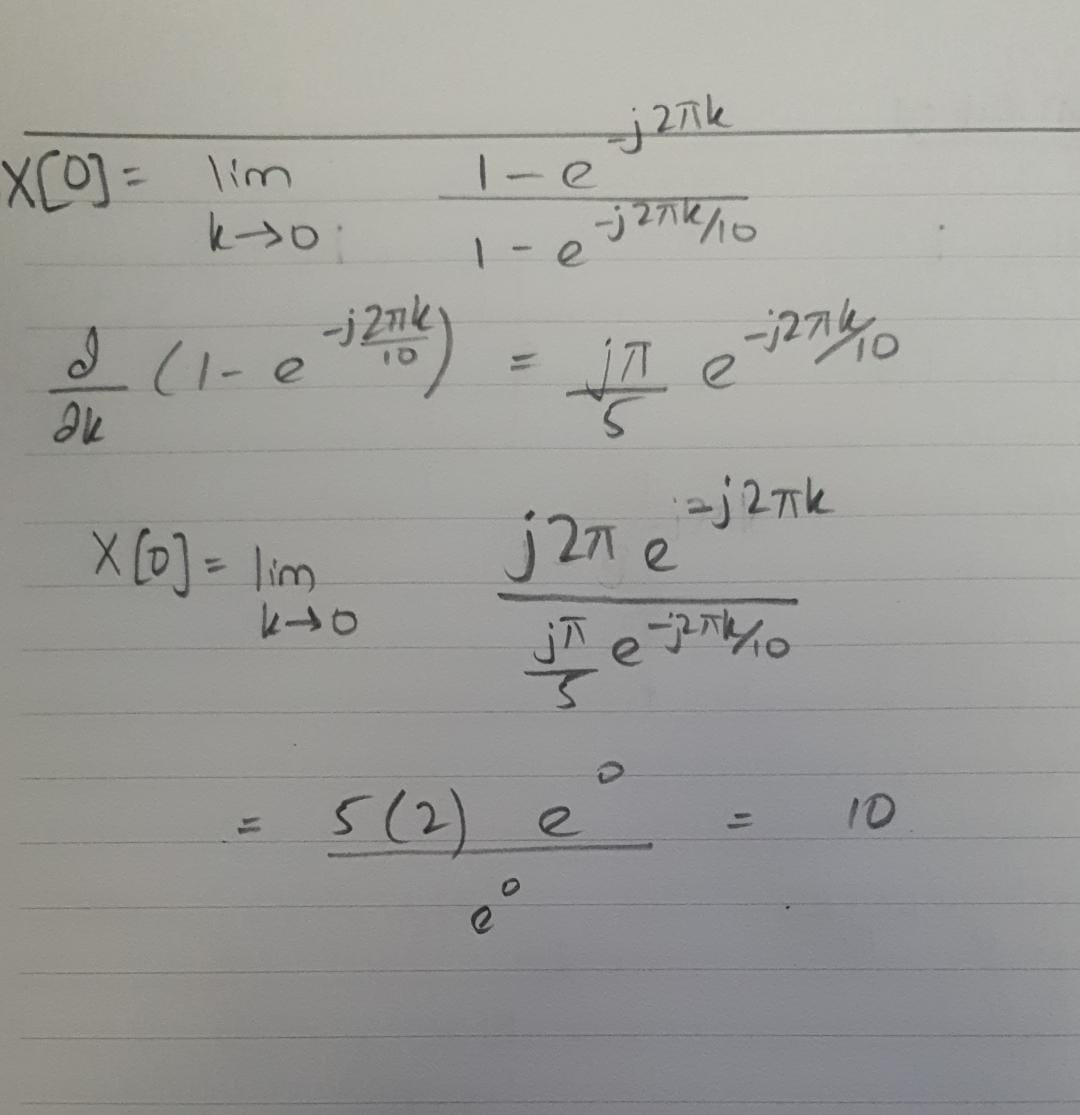

- **Equation Verification**:Using the finite geometric series formula, the derived expression matches the analytical expression for k=0, 1,…,9

- **L’Hospital’s Rule**:Applying L'Hospital's rule at k=0k = 0k=0 shows that X[0]=10. This proves that at zero frequency, the sum of the signal amplitudes is equal to the total number of points (10). This is also evident from the plots.

**Activity 1.2**

x=[0,0,0,0,0,1,1,1,1,1];
N=length(x);
disp("Activity 1.2")

Activity 1.2


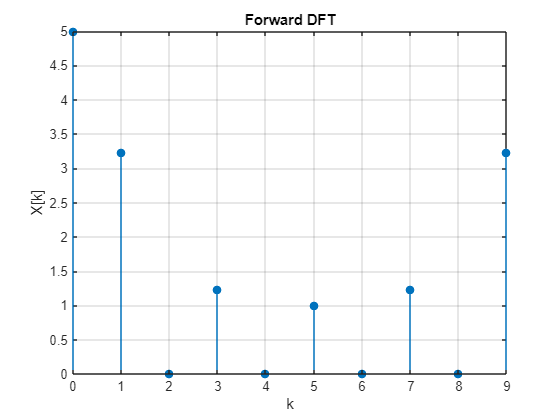

X =    5.0000 + 0.0000i  -1.0000 + 3.0777i  -0.0000 + 0.0000i  -1.0000 + 0.7265i   0.0000 - 0.0000i  -1.0000 - 0.0000i   0.0000 - 0.0000i  -1.0000 - 0.7265i   0.0000 - 0.0000i  -1.0000 - 3.0777i


% forward dft
X = fdft(x,N)

This is complex values. We'll plot phase spectrum. The amplitude plot is basically forward dft, plotted above.

% phase spectrum using angle
phase_spectrum = angle(X);

Just like in section 1.1, we apply our DFT function to the given signal and subsequently recover the original input signal using the IDFT. The magnitude (absolute) plot of the DFT illustrates the strength of each frequency component in the signal, with peaks highlighting the dominant frequencies. Meanwhile, the phase plot shows the relative phase shift of each frequency component, offering insights into how these frequencies align with one another. Together, these graphs give a comprehensive picture of the frequency content of the signal, which is crucial for accurately reconstructing it.

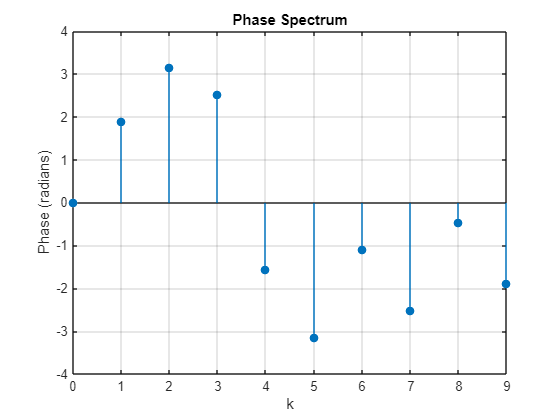

% Create the phase spectrum stem plot
stem(N_arr, phase_spectrum, 'filled');
xlabel('k');
ylabel('Phase (radians)');
title('Phase Spectrum');
grid on;

Now, for the inverse dft

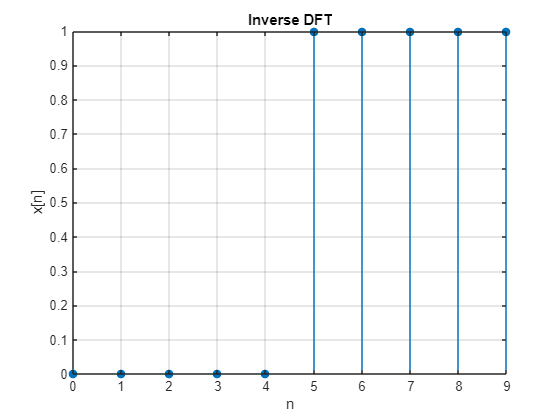

x_idft = idft(X,N);

Since we have a complex valued signal in frequency domain, it means there's no even or odd symmetry in time domain.

**. ****Key Observations:**

- **Reconstruction Accuracy:** The iDFT returns the original signal exactly, demonstrating the DFT's ability to fully represent discrete-time signals.

- The original signal is not symmetric, this results in the dft being complex valued. In part a, there was symmetry of signal in time domain, which resulted in the signal being real valued in frequency domain.

- Also we display only the amplitude when it comes forward dft, since that is what's significant and meanigingful.

**Activity 1.3**

disp("Activity 1.3")

Activity 1.3


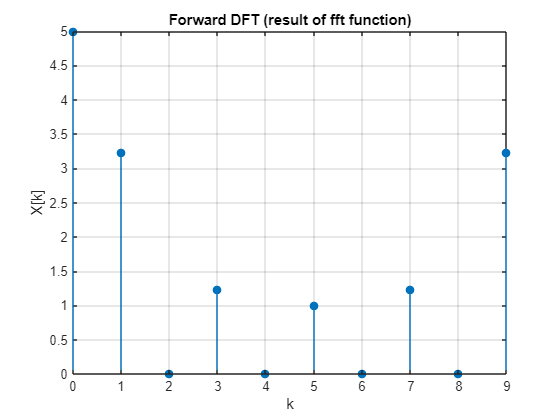


X=fft(x,N);
stem(N_arr, abs(X), 'filled')
xlim([0 N-1])
ylim([0 abs(max(X))])
xlabel("k")
ylabel("X[k]")
title("Forward DFT (result of fft function)");
grid on

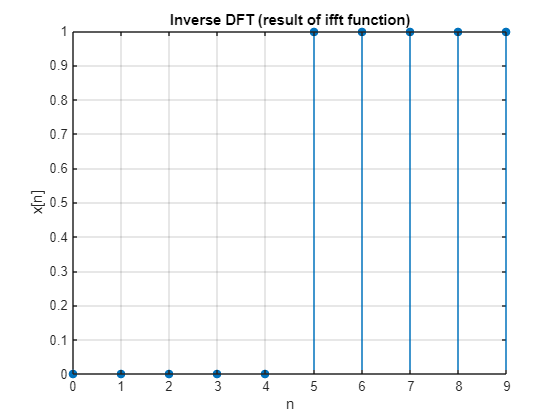


x=ifft(X,N);
stem(N_arr, abs(x), 'filled')
xlim([0 N-1])
ylim([0 abs(max(x))])
xlabel("n")
ylabel("x[n]")
title("Inverse DFT (result of ifft function)");
grid on

Upon using the built in functions, we get the same results for forward and inverse dft as in previous part. This verifies the functions I wrote

**Activity 1.4**

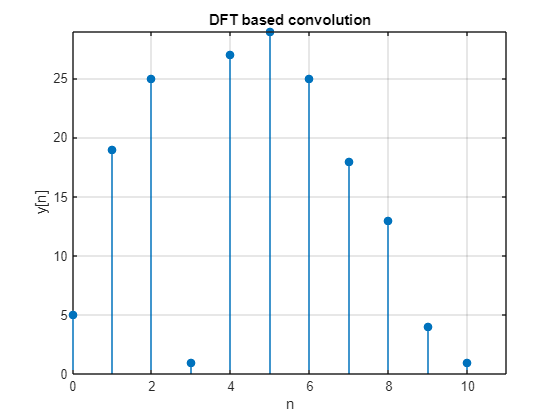

x = [1,3,2,-4,6,2,1];
h = [5,4,3,2,1];
y = dft_based_conv(x,h);

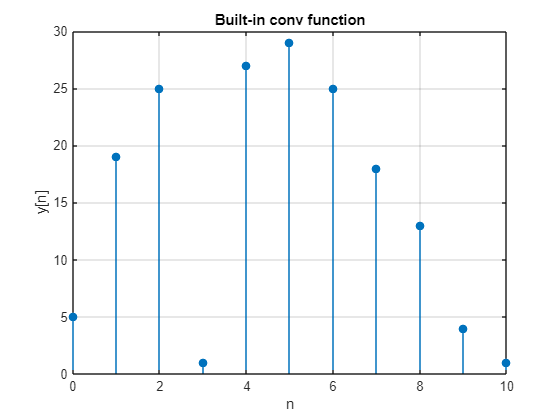


y2= conv(x,h);

Nx= length(x);
Nh= length(h);
Ny = Nx+ Nh -1;
N_arr = 0: Ny-1;
stem(N_arr,abs(y2), "filled")
xlabel("n")
ylabel("y[n]")
title("Built-in conv function");
grid on


disp("Same results from both the linear convolution and dft based")

Same results from both the linear convolution and dft based


We get same results from both the dft based convolution and the built in function, which verifies my logic in the dft based conv function. The detailed comments are provided in the respective function.

Convolution in the time domain corresponds to point-wise multiplication in the frequency domain. The function starts by determining the output length  (N) and then zero-pads both signals to match that length. Next, it calculates the DFTs of the padded signals, multiplies these DFTs together element-wise, and then performs the inverse DFT to get the convolution result. A stem plot is used to visualize this output.

The convolution result contains 11 values, which is expected based on the formula. The output begins at a low value, rises to a peak, and then gradually decreases. A negative peak appears as well, indicating the differences between the two functions. The highest values occur when h[n] aligns with the most significant sections of x[n], while lower values indicate less overlap. The results confirm that the DFT-based convolution is working correctly, as they match those produced by MATLAB's `conv()` function. This illustrates how h[n] interacts with and modifies x[n] when the two signals are combined.

**Activity 1.5**

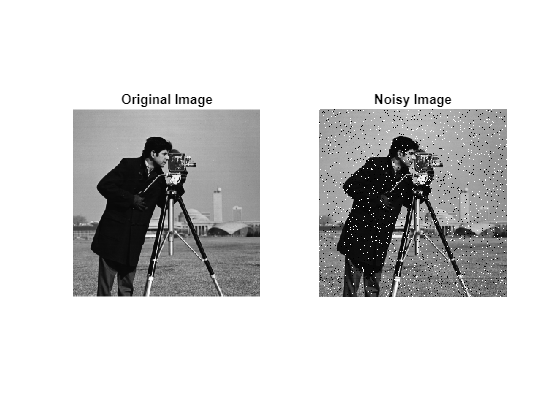

xn=imread('cameraman.tif'); 
xn_noisy=imnoise(xn,'salt & pepper',0.05);

figure;
subplot(1, 2, 1); 
imshow(xn);
title('Original Image');

subplot(1, 2, 2); 
imshow(xn_noisy);
title('Noisy Image');

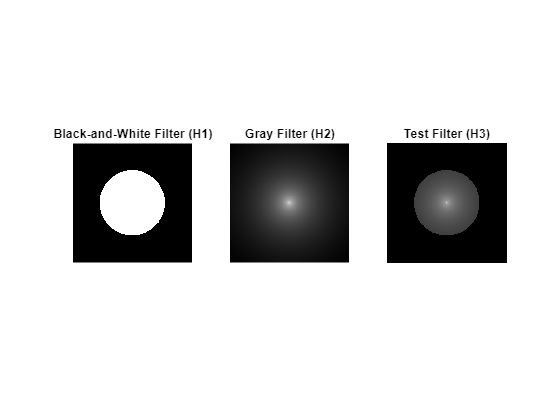


xn_noisy_double = double(xn_noisy);  

X = fft2(xn_noisy_double); 
X_shifted = fftshift(X); 
[M, N] = size(X_shifted);  

% Create the meshgrid for filter design
[U, V] = meshgrid(1:N, 1:M);
D1 = 70; D2 = 50; p = 1/2; 
% For image size 256 x 256, the values
% of D1 and D2 are usually less than 100, and 0 < p <= 2.
D = sqrt((U - N/2).^2 + (V - M/2).^2);
H1k = D <= D1;  % Black-and-white filter (1 inside circle, 0 outside)
H2k = exp(-(D/D2).^p);  % Gray filter (Gaussian-like)
H3k =  H2k.*H1k + (D<=2)/4;

% Plot the transfer functions H1 and H2 using imshow
figure;
subplot(1, 3, 1);
imshow(H1k, []);  % Display the black-and-white filter
title('Black-and-White Filter (H1)');

subplot(1, 3, 2);
imshow(H2k, []);  % Display the gray filter
title('Gray Filter (H2)');

subplot(1, 3, 3);
imshow(H3k, []);  % Display the gray filter
title('Test Filter (H3)');


disp("Ideal LPF is the black and white filter. Whereas, the gray filter is the first-order LPF")

Ideal LPF is the black and white filter. Whereas, the gray filter is the first-order LPF


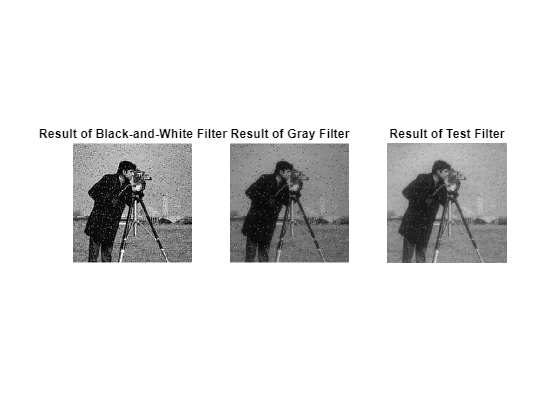


Y1 = X_shifted .* H1k;  
Y2 = X_shifted .* H2k;  
Y3 = X_shifted .* H3k;  

Y1_shifted = ifftshift(Y1);  
Y2_shifted = ifftshift(Y2);  
Y3_shifted = ifftshift(Y3);  

y1 = ifft2(Y1_shifted);  
y2 = ifft2(Y2_shifted);  
y3 = ifft2(Y3_shifted);  

y1_uint8 = uint8(real(y1));  
y2_uint8 = uint8(real(y2));  
y3_uint8 = uint8(real(y3));  

figure;
subplot(1, 3, 1);
imshow(y1_uint8);  % Display filtered image with H1
title('Result of Black-and-White Filter');

subplot(1, 3, 2);
imshow(y2_uint8);  % Display filtered image with H2
title('Result of Gray Filter');

subplot(1, 3, 3);
imshow(y3_uint8);  % Display filtered image with H2
title('Result of Test Filter');

## **Noise Filtering in the Frequency Domain**

By utilizing the black-and-white (H1) and gray (H2) filters in the frequency domain, we were able to reduce noise which are basically the high-frequency components. TheH1 filter effectively eliminates high-frequency noise, while the H2 filter gradually attenuates these frequencies.

FFT is used to convert the noisy image into the frequency domain, making it easier to target and reduce high-frequency noise, such as salt-and-pepper noise.

## **Results Depiction**

-** Black-and-White Filter (H1)**: Applying this filter yields an image where noise is greatly diminished, as it effectively blocks high-frequency components. The first filtered image will exhibit smoother transitions compared to the original noisy image. This is also the ideal LPF.  There is a sharp contrast, a very clear boundary in the filter, so the resultant image also has visible black and white dots - although they are less obvious than the original image.

- **Gray Filter (H2)**: This filter reduces high frequencies more gradually, allowing it to retain some details while still minimizing noise. The second filtered image will maintain some high-frequency features but will show a noticeable reduction in visible noise when compared to the original noisy version. This is the realistic first order implementation. For H2 filtered image, the dots are gray, not black or white, they are more subtle, image is much more clear. So, the filters have improved the inputs and eliminated the noise.

 **- H3 filter** is a trial run, where we just combine the two. In H3, I also added a DC shift which increased brightness of the filtered image.